Q1.

A.

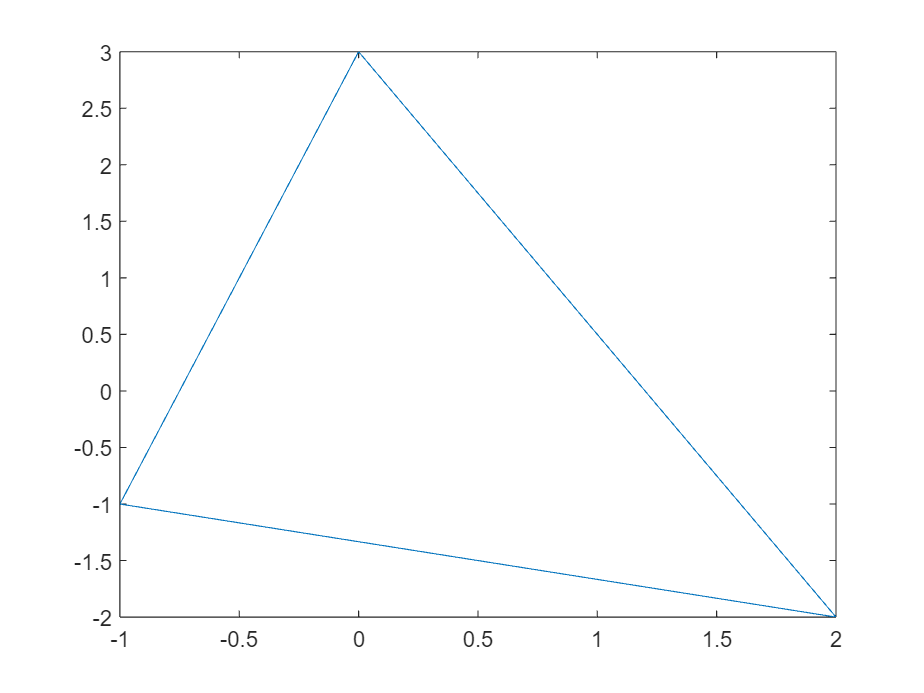

x = [-1 0 2 -1; -1 3 -2 -1]; 
plot(x(1,:), x(2,:))

B.

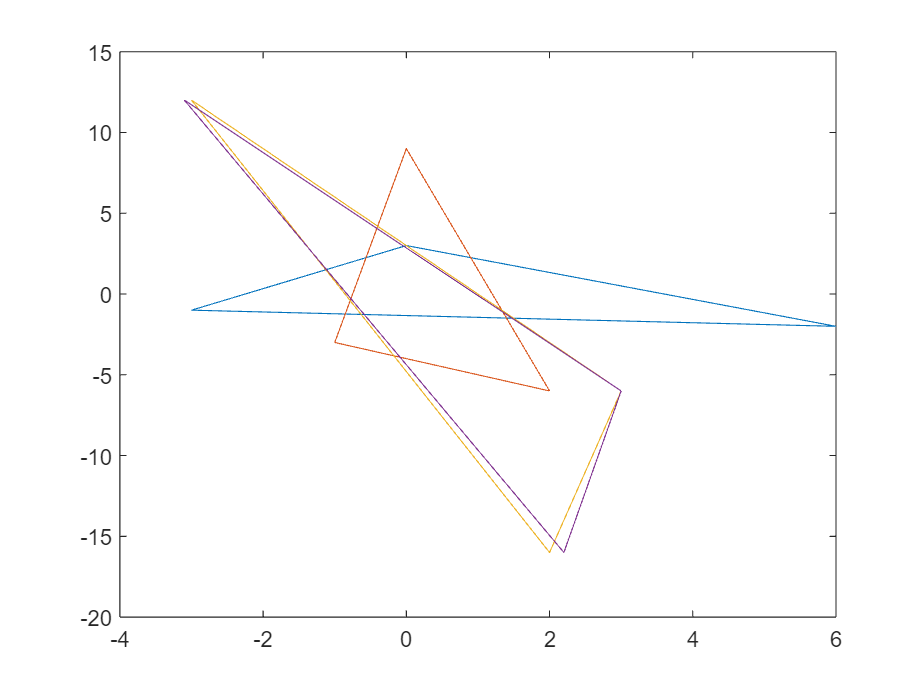

x_tri_vertices = [-1 0 2; -1 3 -2]; 

A1 = [3 0; 0 1];
A2 = [1 0; 0 3];
A3 = [2 1; -10 -2];
A4 = [2.1 1; -10 -2];

A1_x = A1*x_tri_vertices;
new_col = A1_x(:,1);
A1_x = [A1_x new_col];

A2_x = A2*x_tri_vertices;
new_col = A2_x(:,1);
A2_x = [A2_x new_col];

A3_x = A3*x_tri_vertices;
new_col = A3_x(:,1);
A3_x = [A3_x new_col];

A4_x = A4*x_tri_vertices;
new_col = A4_x(:,1);
A4_x = [A4_x new_col];

plot(A1_x(1,:), A1_x(2,:))
hold on
plot(A2_x(1,:), A2_x(2,:))
hold on
plot(A3_x(1,:), A3_x(2,:))
hold on
plot(A4_x(1,:), A4_x(2,:))
hold off

The matrices transform the triangle by either stretching or compressing it as can be seen in the graphs. This is because Matrices act as operations on vectors either scaling them or rotating them.

Q2.

t = 0:0.1:10;
x_0 = [1 1]';
B = [0; 1];
C = [0 1];
D = 0;

A1 = [0 1;-10 -2];
A2 = [-1 1;-10 -2];
A3 = [2 1;-10 -2];
A4 = [2.1 1; -10 -2];

eig(A1)

ans =   -1.0000 + 3.0000i
  -1.0000 - 3.0000i


eig(A2)

ans =   -1.5000 + 3.1225i
  -1.5000 - 3.1225i


eig(A3)

ans =    0.0000 + 2.4495i
   0.0000 - 2.4495i


eig(A4)

ans =    0.0500 + 2.4078i
   0.0500 - 2.4078i


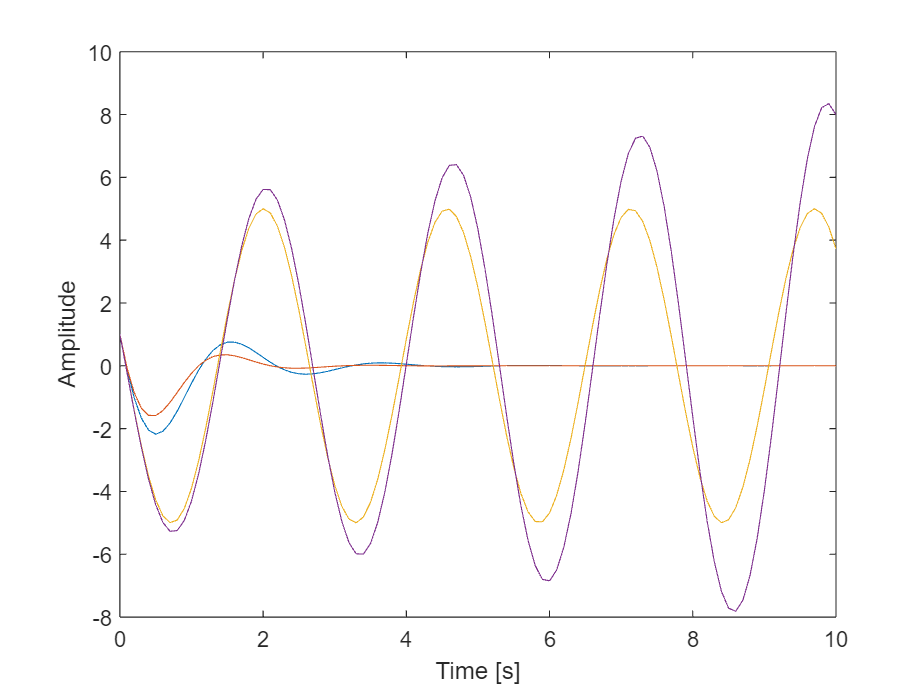


sys1 = ss(A1,B,C,D);
sys2 = ss(A2,B,C,D);
sys3 = ss(A3,B,C,D);
sys4 = ss(A4,B,C,D);

u = 0*t;
[y1,t] = lsim(sys1, u, t, x_0);
[y2,t] = lsim(sys2, u, t, x_0);
[y3,t] = lsim(sys3, u, t, x_0);
[y4,t] = lsim(sys4, u, t, x_0);

plot(t, y1);
hold on
plot(t, y2);
hold on
plot(t, y3);
hold on
plot(t, y4);
hold off
xlabel('Time [s]')
ylabel('Amplitude')

The stability of a system is directly related to the real part of its eigenvalues. If the real part is negative, the system is marginal; and if it is positive, the system is unstable. This concept can be demonstrated through the plots of the system outputs, where sys1 and sys2 exhibit stability, sys3 shows marginal stability with constant amplitude oscillations, and sys4 is unstable with increasing amplitude oscillations due to its positive real part. 

Q3.

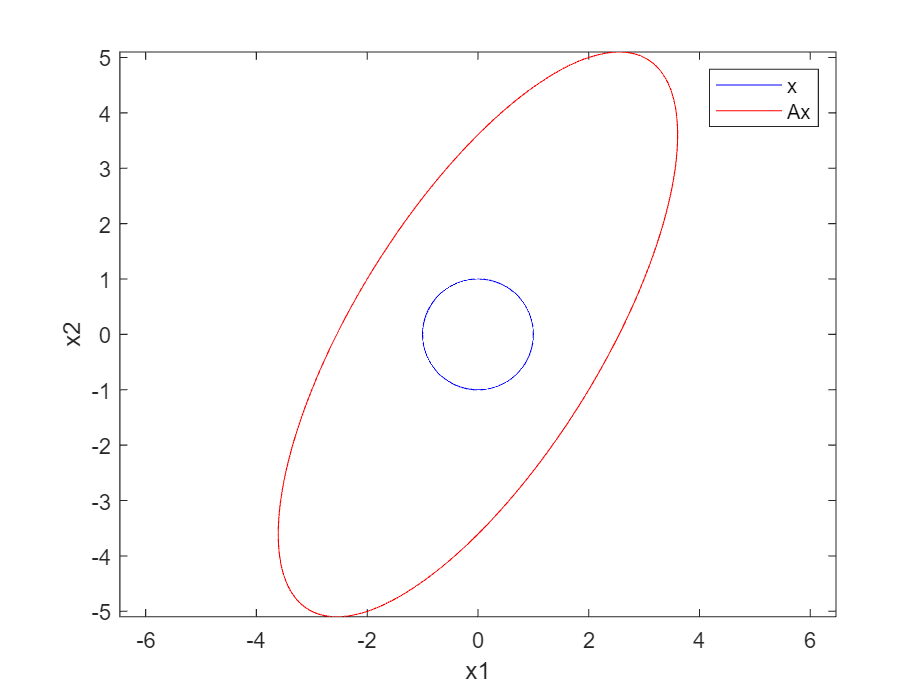

theta = linspace(0, 2*pi, 1000);
x_c = [cos(theta); sin(theta)];
A_c = [2 3;5 1];
Ax = A_c * x_c;

plot(x_c(1,:), x_c(2,:), 'b-');
hold on
plot(Ax(1,:), Ax(2,:), 'r-');
legend('x', 'Ax');
xlabel('x1');
ylabel('x2');
axis equal;
hold off 


normA= norm(A_c);
disp("2-norm of A: " + normA);

2-norm of A: 5.8339



svd_norm = norm(svd(A_c));
disp("svd norm of A: " + svd_norm);

svd norm of A: 6.245



% Find maximum distance from the origin to a point on the transformed unit circle
max_distance = max(sqrt(Ax(1,:).^2 + Ax(2,:).^2));
disp("Maximum distance from the origin to a point on the transformed unit circle: " + max_distance);

Maximum distance from the origin to a point on the transformed unit circle: 5.8339


The value of the max distance from the origin to a point on the transformed unit circle is the same as the 2-norm of the transformed unit circle. 

The 2-norm and the SVD norm of a matrix are two different measures of the magnitude of the matrix. The 2-norm is the largest singular value of the matrix, which represents the magnitude of the largest linear transformation performed by the matrix. On the other hand, the SVD norm of a matrix is the square root of the sum of the squares of all the singular values of the matrix, which represents the overall magnitude of all the linear transformations performed by the matrix.

Q4.

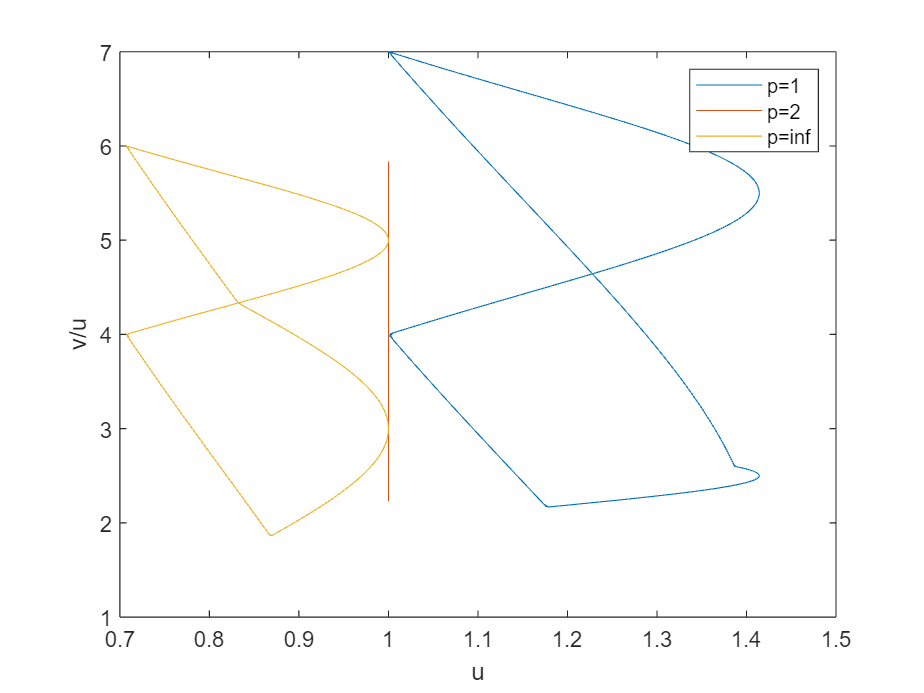

p = [1, 2, inf]; % The different p values

x = [cos(theta); sin(theta)]; % The unit circle
A = [2 3;5 1]; % The matrix A
Ax = A * x; % The transformed unit circle

for i = 1:length(p)
u = vecnorm(x, p(i), 1); % Find the norm of x for each column
v = vecnorm(Ax, p(i), 1); % Find the norm of Ax for each column
plot(u, v./u); % Plot u against v/u
hold on
end

legend('p=1', 'p=2', 'p=inf');
xlabel('u');
ylabel('v/u');